% Week 11 example code for training a simple SVM classifier on the
% CUB_200_2011_Subset20classes dataset using HOG features. Instead of using
% the full images, we only use the bounding box area defined in
% bounding_boxes.txt.
%
% Authors: Roland Goecke and James Ireland.
% Date created: 02/05/2022
% Modified by Ibrahim Radwan
% Date last updated: 11/04/25

close all;
clear variables;
existing_GUIs = findall(0);
if length(existing_GUIs) > 1
    delete(existing_GUIs);
end
clc;

## Read the training, validation and test partitions from the relevant

%folder = "Data\CUB_200_2011_Subset20classes\";
%folder = "P:\CUB_200_2011_Subset20classes\";
%folder = "/Users/s423738/Dropbox/UC/Teaching/8890_CVIA_PG/2022/Data/CUB_200_2011_Subset20classes/";
folder = "H:\computer-vision\assignment_1\data\CUB_200_2011_Subset20classes\";
trainingImageNames = readtable(fullfile(folder, "train.txt"), ...
    'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(folder + "validate.txt", ...
    'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(folder + "test.txt", ...
    'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(folder + "classes.txt", ...
    'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(folder + "image_class_labels.txt", ...
    'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Read bounding box information from bounding_boxes.txt. The format is

boundingBoxes = readtable(folder + "bounding_boxes.txt", ...
    'ReadVariableNames', false);
boundingBoxes.Properties.VariableNames = {'index', 'x', 'y', 'w', 'h'};

% Map bounding box information to the respective image file name
train_image_box_map = returnMapping(trainingImageNames, boundingBoxes);
val_image_box_map = returnMapping(validationImageNames, boundingBoxes);
test_image_box_map = returnMapping(testImageNames, boundingBoxes);

## Create lists of image names for training, validation and test subsets.

trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

This is where the image cropping based on the bounding box information happens through the readImagesIntoDatastoreBB_Fast function and related helper functions.

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, train_image_box_map);
disp('Training set class samples:');

Training set class samples:


countEachLabel(trainingImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  



validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, val_image_box_map);
disp('Validation set class samples:');

Validation set class samples:


countEachLabel(validationImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  



testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames',   'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, test_image_box_map);
disp('Test set class samples:');

Test set class samples:


countEachLabel(testImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  


## The images all have different spatial resolutions (width x height), so

% Combine transformed datastores and labels
labelsTraining = arrayDatastore(trainingImageDS.Labels);
labelsValidation = arrayDatastore(validationImageDS.Labels);
labelsTest = arrayDatastore(testImageDS.Labels);

cdsTraining = combine(trainingImageDS, labelsTraining);
cdsValidation = combine(validationImageDS, labelsValidation);
cdsTest = combine(testImageDS, labelsTest);

% Resize all images to a common width and height
targetSize = [100, 100];
cdsTraining = transform(cdsTraining, @(x) preprocessData(x,targetSize));
cdsValidation = transform(cdsValidation, @(x) preprocessData(x,targetSize));
cdsTest = transform(cdsTest, @(x) preprocessData(x,targetSize));

## Display a sample image from the datastore and HOG features

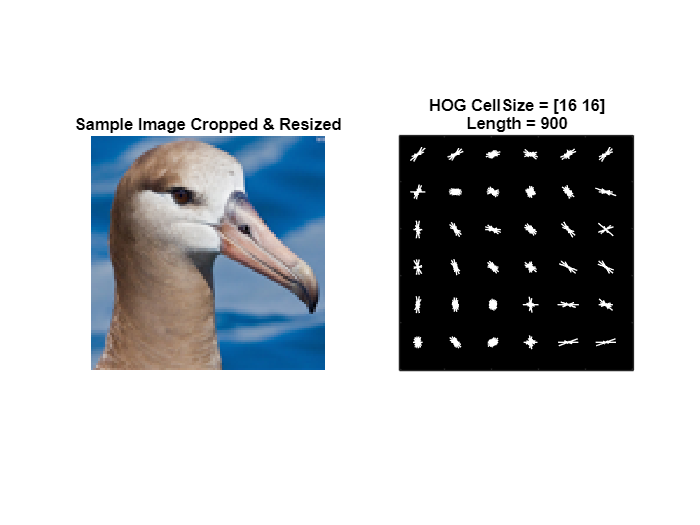

figure(1);
img = cdsTraining.read{1};
[hog_16x16, vis16x16] = extractHOGFeatures(img,'CellSize',[16 16]);
%[hog_8x8, vis8x8] = extractHOGFeatures(img,'CellSize',[8 8]);
subplot(1, 2, 1);
imshow(img);
title('Sample Image Cropped & Resized');
subplot(1, 2, 2);
plot(vis16x16);
%plot(vis8x8);
title({'HOG CellSize = [16 16]'; ['Length = ' num2str(length(hog_16x16))]});

%title({'HOG CellSize = [8 8]'; ['Length = ' num2str(length(hog_8x8))]});

## Extract HOG features

cellSize = [16 16];     % Set cell size to 16x16
hogFeatureSize = length(hog_16x16);
%cellSize = [8 8];     % Set cell size to 8x8
%hogFeatureSize = length(hog_8x8);

% Start by extracting HOG features from the training set. These features
% will be used to train the classifier.
% Loop over the trainingSet and extract HOG features from each image.
numImagesTrain = numel(cdsTraining.UnderlyingDatastores{1, 1}.UnderlyingDatastores{1, 1}.Files);
trainingFeatures = zeros(numImagesTrain, hogFeatureSize, 'single');
reset(cdsTraining);     % Make sure we start with the first image
for i = 1:numImagesTrain
    imgFromDS = read(cdsTraining);    % Get item from datastore. Note, this returns a cell array.
    imgGray = im2gray(imgFromDS{1});      % Ensure images are grayscale

    trainingFeatures(i, :) = extractHOGFeatures(imgGray, 'CellSize', cellSize);
end

% Now extract HOG features from the test set as well.
numImagesTest = numel(cdsTest.UnderlyingDatastores{1, 1}.UnderlyingDatastores{1, 1}.Files);
testFeatures = zeros(numImagesTest, hogFeatureSize, 'single');
reset(cdsTest);     % Make sure we start with the first image
for i = 1:numImagesTest
    imgFromDS = read(cdsTest);    % Get item from datastore
    imgGray = im2gray(imgFromDS{1});  % Ensure images are grayscale

    testFeatures(i, :) = extractHOGFeatures(imgGray, 'CellSize', cellSize);
end

## Check if we have a GPU available and clear any old data from it

if (gpuDeviceCount() > 0)
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

## Train a multi-class SVM

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.
Copying objective function to workers...
Done copying objective function to workers.
|================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |
|================================================================================================|
|    1 |       8 | Best   |     0.83784 |      4.9676 |     0.83784 |     0.83784 |       61.452 |


The error message follows:
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.
|    2 |       8 | Best   |     0.78829 |       5.227 |     0.78829 |     0.81306 |       19.816 |
|    3 |       8 | Accept |      0.7988 |      6.8661 |     0.78829 |     0.80831 |    3.091e-08 |
|    4 |       8 | Accept |     0.86186 |      2.1925 |     0.78829 |      0.8217 |       149.17 |
|    5 |       8 | Accept |      0.8048 |      9.8347 |     0.78829 |     0.81832 |   4.1637e-07 |
|    6 |       8 | Accept |      0.8018 |       9.964 |     0.78829 |     0.81557 |   4.2735e-07 |
|    7 |       8 | Accept |     0.81832 |      10.672 |     0.78829 |     0.81596 |   1.6467e-06 |
|    8 |       8 | Accept |      0.8033 |      4.5167 |     0.78829 |     0.81438 |   1.5036e-08 |
|    9 |       8 | Accept |      0.8048 |      6.2881 |     0.78829 |     0.78869 |   2.7389e-07 |
|   10 |       8 | Accept |      0

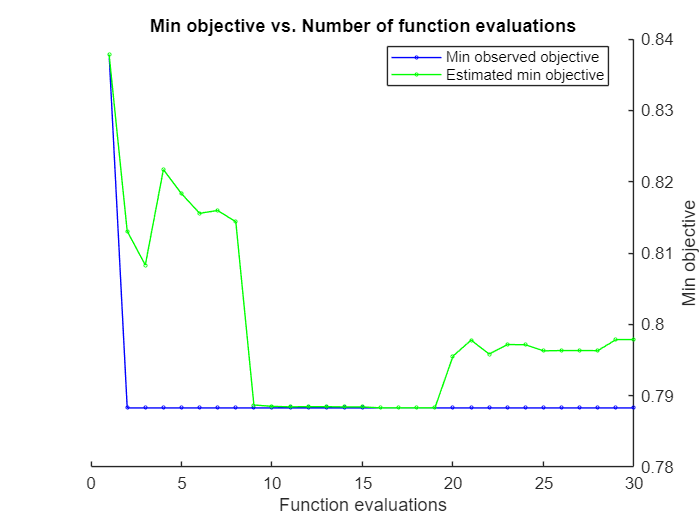

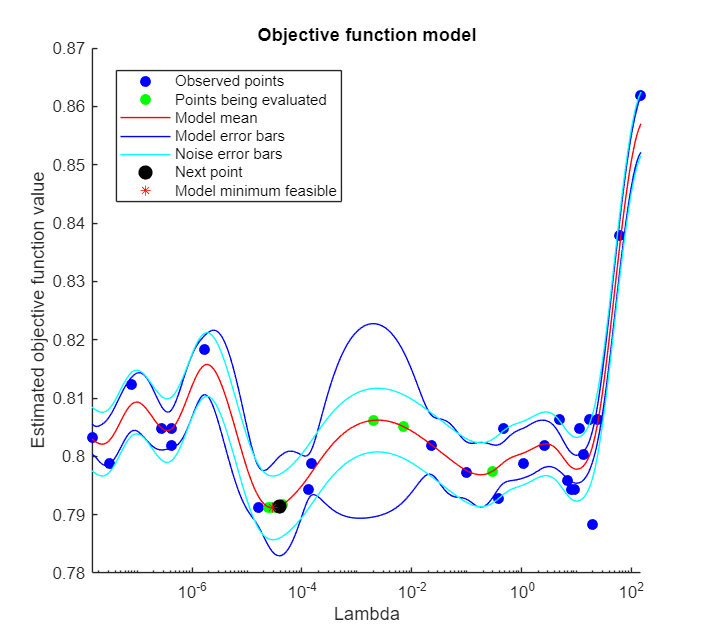

t = templateLinear('Solver', 'lbfgs');
%t = templateSVM('KernelFunction','linear');
options = struct('UseParallel', true);

% fitcecoc uses multiple SVM learners and a 'One-vs-One' encoding scheme.
Classifier = fitcecoc(trainingFeatures, trainingImageDS.Labels, 'Coding', 'onevsall', 'Learners', t, ...
    'OptimizeHyperparameters', {'Lambda'}, ...
    'HyperparameterOptimizationOptions', options);

% Classifier = fitcecoc(trainingFeatures, trainingImageDS.Labels, 'Learners', t, ...
%     'FitPosterior',true,'Verbose',2);

## Test the accuracy on the test partition

YPred = predict(Classifier, testFeatures);
YTest = testImageDS.Labels;

% Calculate overall accuracy
accuracy = sum(YPred == YTest)/numel(YTest) % Output on command line

accuracy = 0.2162

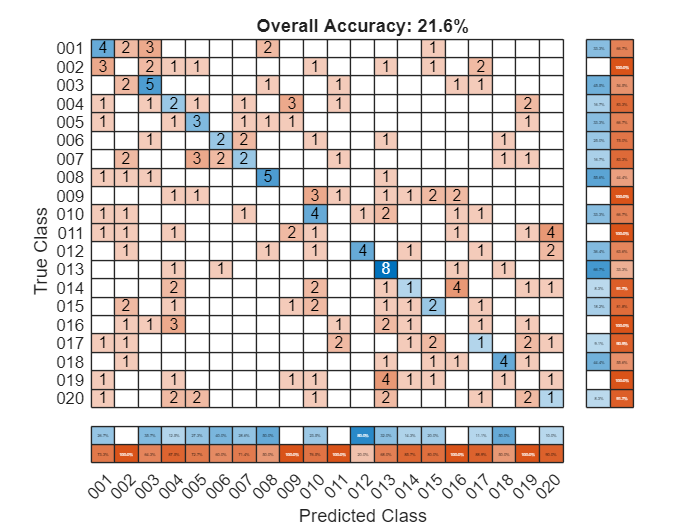


% Show confusion matrix in figure
[m, order] = confusionmat(YTest, YPred);
figure(2);
cm = confusionchart(m, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title("Overall Accuracy: "+ string(round(accuracy*100, 1)) +"%");

## Compute classwise positive recogniton rate

classwisePosRecog = zeros(height(order), 1);
samplesPerRow = sum(m, 2);
for iI = 1:height(order)
    classwisePosRecog(iI) = round(100 * m(iI, iI) / samplesPerRow(iI), 1);
end
disp('Classwise Recognition Rates:');

Classwise Recognition Rates:


disp(classwisePosRecog)

   33.3000
         0
   45.5000
   16.7000
   33.3000
   25.0000
   16.7000
   55.6000
         0
   33.3000
         0
   36.4000
   66.7000
    8.3000
   18.2000
         0
    9.1000
   44.4000
         0
    8.3000



## Helper function for resizing images in transform

function data_out = preprocessData(data, targetSize)
try
    data_out{1} = imresize(data{1}, targetSize(1:2)); % Resize images
    data_out{2} = data{2};  % Keep labels as they are
catch e
    % This is solely for debugging
    disp(e)
end
end

## Helper function mapping image names to bounding boxes and vice versa

function image_box_map = returnMapping(ImageNames, boundingBoxes)
image_box_map = containers.Map;
for i = 1:size(ImageNames, 1)
    fn = ImageNames{i,2}{1};
    fn = split(fn, "\");
    fn = split(fn, "/");
    image_box_map(fn{end}) = [boundingBoxes{ImageNames{i,1}, 2:5}];
end
end